% EC_protected_to_fmu
%
% 
%
%
% Copyright (c) 2024 Third Equation LTD.
%
%
%**************************************************************************
% Revision history
% Date      Author
%**************************************************************************
% 15/02/24  veimar.moreno@thirdequation.com
%           First issue.
%**************************************************************************
%                                                                          
%  Modification history of definition file provided for version matching   
%                                                                         
%  Version  Date        Author      Revision Details                            
%  0.0      15/02/24     VM          Initial issue.                             
% *************************************************************************

## Export Simulink Model to Standalone FMU with Tunable Parameters

This section illustrates how to export Simulink model with external references to a Standalone FMU with tunable parameters. 

% open model EC_control.slx model
model = "EC_control";
open_system(model);

From **Simulation** tab select **Save > Save as... **go to the *EC_ctrl* folder and type *EC_control_protected* in the *File name *field.

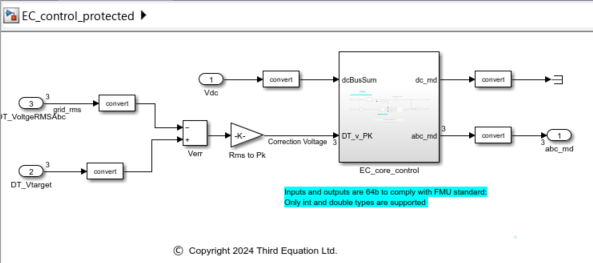

Replace the *EC_core_control* block with a *Model* block referencing the *EC_core_control.slxp* protected model.

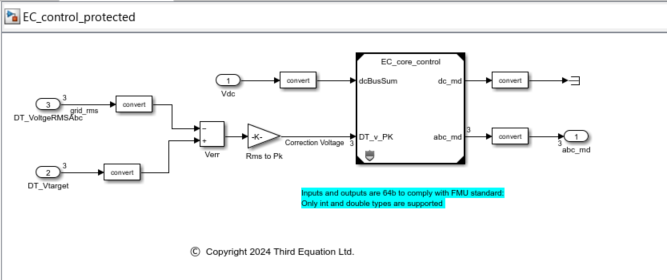

Go to the **Simulation** tab and select **Save** >** Standalone FMU**. The figure below shows the Export Standalone FMU dialog.

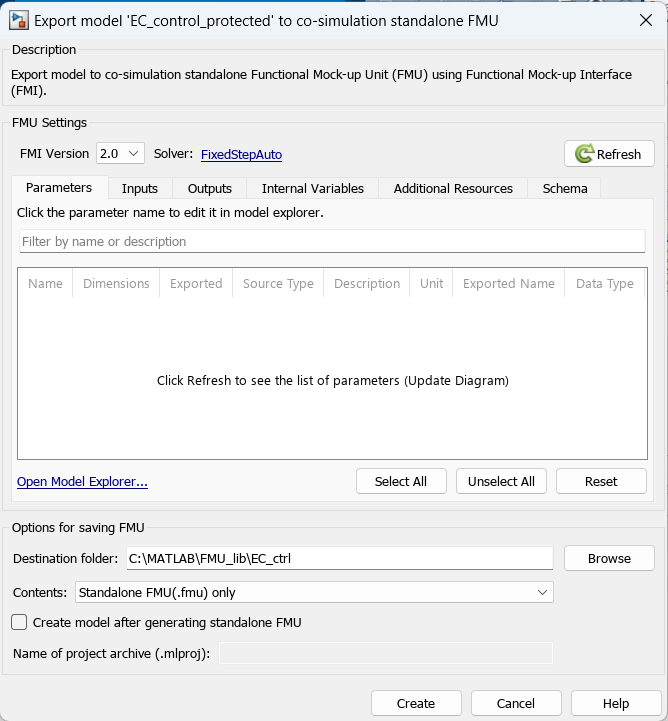

Click on **Create**.

% export model nex_control to standalone FMU
model = "EC_control";
exportToFMU2CS(model,'CreateModelAfterGeneratingFMU', 'on');

Setting Hardware Implementation > Device Type to 'MATLAB Host' for model 'EC_control_protected'.


### 'GenerateComments' is disabled for Co-Simulation Standalone FMU Export.



Build Summary

Top model targets built:

Model                 Action                        Rebuild Reason                                    
EC_control_protected  Code generated and compiled.  Code generation information file does not exist.  

1 of 1 models built (0 models already up to date)
Build duration: 0h 0m 29.446s
### Model was successfully exported to co-simulation standalone FMU: 'C:\Users\Veimar\thirdequation.com\TNEI Model - Documents\MATLAB\FMU_lib\EC_ctrl\EC_control_protected.fmu'.


close_system(model);

The *EC_control.fmu* standalone FMU is generated.

*Copyright 2024 Third Edquation Ltd.*